% Desglosamos los valores en sus respectivas componentes
[vector_tiempo_tendon,posicion_nodo_0_dcha_tendon,posicion_nodo_28_central_tendon,posicion_nodo_56_izq_tendon] = readvars('properties_0-28-56_tendon_x.txt');
[vector_tiempo_fiber,posicion_nodo_0_dcha_fiber,posicion_nodo_28_central_fiber,posicion_nodo_56_izq_fiber] = readvars('properties_0-28-56_fiber_x.txt');
[vector_tiempo_laton,posicion_nodo_0_dcha_laton,posicion_nodo_28_central_laton,posicion_nodo_56_izq_laton] = readvars('properties_0-28-56_laton_x.txt');
[vector_tiempo_laton_22_5,posicion_nodo_0_dcha_laton_22_5,posicion_nodo_28_central_laton_22_5,posicion_nodo_56_izq_laton_22_5] = readvars('properties_0-28-56_laton_x_22.5.txt');
[vector_tiempo_laton_25,posicion_nodo_0_dcha_laton_25,posicion_nodo_28_central_laton_25,posicion_nodo_56_izq_laton_25] = readvars('properties_0-28-56_laton_x_25.txt');
[vector_tiempo_laton_30,posicion_nodo_0_dcha_laton_30,posicion_nodo_28_central_laton_30,posicion_nodo_56_izq_laton_30] = readvars('properties_0-28-56_laton_x_30.txt');

 % Expresion que ayuda a dividir la celda cada que encontramos un espacio en el vector
expression = ' ';

% Dividimos la cadena en la misma variable pero con celdas separadas según
% hemos indicado en la variable expresión. Es decir que ashora por cada
% fila tendremos a su vez una celda dividida en 7 celdas más pequeñas
posicion_nodo_0_dcha_split_fiber = regexp(posicion_nodo_0_dcha_fiber,expression,'split');
posicion_nodo_28_central_split_fiber = regexp(posicion_nodo_28_central_fiber,expression,'split');
posicion_nodo_56_izq_split_fiber = regexp(posicion_nodo_56_izq_fiber,expression,'split');

posicion_nodo_0_dcha_split_tendon = regexp(posicion_nodo_0_dcha_tendon,expression,'split');
posicion_nodo_28_central_split_tendon = regexp(posicion_nodo_28_central_tendon,expression,'split');
posicion_nodo_56_izq_split_tendon = regexp(posicion_nodo_56_izq_tendon,expression,'split');

posicion_nodo_0_dcha_split_laton = regexp(posicion_nodo_0_dcha_laton,expression,'split');
posicion_nodo_28_central_split_laton = regexp(posicion_nodo_28_central_laton,expression,'split');
posicion_nodo_56_izq_split_laton = regexp(posicion_nodo_56_izq_laton,expression,'split');

posicion_nodo_0_dcha_split_laton_22_5 = regexp(posicion_nodo_0_dcha_laton_22_5,expression,'split');
posicion_nodo_28_central_split_laton_22_5 = regexp(posicion_nodo_28_central_laton_22_5,expression,'split');
posicion_nodo_56_izq_split_laton_22_5 = regexp(posicion_nodo_56_izq_laton_22_5,expression,'split');

posicion_nodo_0_dcha_split_laton_25 = regexp(posicion_nodo_0_dcha_laton_25,expression,'split');
posicion_nodo_28_central_split_laton_25 = regexp(posicion_nodo_28_central_laton_25,expression,'split');
posicion_nodo_56_izq_split_laton_25 = regexp(posicion_nodo_56_izq_laton_25,expression,'split');

posicion_nodo_0_dcha_split_laton_30 = regexp(posicion_nodo_0_dcha_laton_30,expression,'split');
posicion_nodo_28_central_split_laton_30 = regexp(posicion_nodo_28_central_laton_30,expression,'split');
posicion_nodo_56_izq_split_laton_30 = regexp(posicion_nodo_56_izq_laton_30,expression,'split');

% Recolectamos los datos y los metemos en una matriz
for i=1:length(posicion_nodo_0_dcha_split_fiber)
    
    % Guardamos el valor de la celda en una variable
    posicion_nodo_0_dcha_split_fiber_ = posicion_nodo_0_dcha_split_fiber{i,1};
    posicion_nodo_28_central_split_fiber_ = posicion_nodo_28_central_split_fiber{i,1};
    posicion_nodo_56_izq_split_fiber_ = posicion_nodo_56_izq_split_fiber{i,1};
    
    % Entramos en la subcelda y metemos cada valor de la fila en una
    % matriz, convirtiéndolo en un valor numérico
    for j=1:length(posicion_nodo_0_dcha_split_fiber_)
        
        posicion_nodo_0_dcha_split_num_fiber = cell2mat(posicion_nodo_0_dcha_split_fiber_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_fiber = cell2mat(posicion_nodo_28_central_split_fiber_(1,j));
        posicion_nodo_56_izq_split_num_fiber = cell2mat(posicion_nodo_56_izq_split_fiber_(1,j));
        
        posiciones_nodo_0_fiber(i,j) = str2double(posicion_nodo_0_dcha_split_num_fiber);
        posiciones_nodo_28_fiber(i,j) = str2double(posicion_nodo_28_central_split_num_fiber);
        posiciones_nodo_56_fiber(i,j) = str2double(posicion_nodo_56_izq_split_num_fiber);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_tendon)
    
    % Guardamos el valor de la celda en una variable
    posicion_nodo_0_dcha_split_tendon_ = posicion_nodo_0_dcha_split_tendon{i,1};
    posicion_nodo_28_central_split_tendon_ = posicion_nodo_28_central_split_tendon{i,1};
    posicion_nodo_56_izq_split_tendon_ = posicion_nodo_56_izq_split_tendon{i,1};
    
    % Entramos en la subcelda y metemos cada valor de la fila en una
    % matriz, convirtiéndolo en un valor numérico
    for j=1:length(posicion_nodo_0_dcha_split_tendon_)
        
        posicion_nodo_0_dcha_split_num_tendon = cell2mat(posicion_nodo_0_dcha_split_tendon_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_tendon = cell2mat(posicion_nodo_28_central_split_tendon_(1,j));
        posicion_nodo_56_izq_split_num_tendon = cell2mat(posicion_nodo_56_izq_split_tendon_(1,j));
        
        posiciones_nodo_0_tendon(i,j) = str2double(posicion_nodo_0_dcha_split_num_tendon);
        posiciones_nodo_28_tendon(i,j) = str2double(posicion_nodo_28_central_split_num_tendon);
        posiciones_nodo_56_tendon(i,j) = str2double(posicion_nodo_56_izq_split_num_tendon);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_laton)
    
    % Guardamos el valor de la celda en una variable
    posicion_nodo_0_dcha_split_laton_ = posicion_nodo_0_dcha_split_laton{i,1};
    posicion_nodo_28_central_split_laton_ = posicion_nodo_28_central_split_laton{i,1};
    posicion_nodo_56_izq_split_laton_ = posicion_nodo_56_izq_split_laton{i,1};
    
    % Entramos en la subcelda y metemos cada valor de la fila en una
    % matriz, convirtiéndolo en un valor numérico
    for j=1:length(posicion_nodo_0_dcha_split_laton_)
        
        posicion_nodo_0_dcha_split_num_laton = cell2mat(posicion_nodo_0_dcha_split_laton_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_laton = cell2mat(posicion_nodo_28_central_split_laton_(1,j));
        posicion_nodo_56_izq_split_num_laton = cell2mat(posicion_nodo_56_izq_split_laton_(1,j));
        
        posiciones_nodo_0_laton(i,j) = str2double(posicion_nodo_0_dcha_split_num_laton);
        posiciones_nodo_28_laton(i,j) = str2double(posicion_nodo_28_central_split_num_laton);
        posiciones_nodo_56_laton(i,j) = str2double(posicion_nodo_56_izq_split_num_laton);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_laton_22_5)
    
    % Guardamos el valor de la celda en una variable
    posicion_nodo_0_dcha_split_laton_22_5_ = posicion_nodo_0_dcha_split_laton_22_5{i,1};
    posicion_nodo_28_central_split_laton_22_5_ = posicion_nodo_28_central_split_laton_22_5{i,1};
    posicion_nodo_56_izq_split_laton_22_5_ = posicion_nodo_56_izq_split_laton_22_5{i,1};
    
    % Entramos en la subcelda y metemos cada valor de la fila en una
    % matriz, convirtiéndolo en un valor numérico
    for j=1:length(posicion_nodo_0_dcha_split_laton_22_5_)
        
        posicion_nodo_0_dcha_split_num_laton_22_5 = cell2mat(posicion_nodo_0_dcha_split_laton_22_5_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_laton_22_5 = cell2mat(posicion_nodo_28_central_split_laton_22_5_(1,j));
        posicion_nodo_56_izq_split_num_laton_22_5 = cell2mat(posicion_nodo_56_izq_split_laton_22_5_(1,j));
        
        posiciones_nodo_0_laton_22_5(i,j) = str2double(posicion_nodo_0_dcha_split_num_laton_22_5);
        posiciones_nodo_28_laton_22_5(i,j) = str2double(posicion_nodo_28_central_split_num_laton_22_5);
        posiciones_nodo_56_laton_22_5(i,j) = str2double(posicion_nodo_56_izq_split_num_laton_22_5);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_laton_25)
    
    % Guardamos el valor de la celda en una variable
    posicion_nodo_0_dcha_split_laton_25_ = posicion_nodo_0_dcha_split_laton_25{i,1};
    posicion_nodo_28_central_split_laton_25_ = posicion_nodo_28_central_split_laton_25{i,1};
    posicion_nodo_56_izq_split_laton_25_ = posicion_nodo_56_izq_split_laton_25{i,1};
    
    % Entramos en la subcelda y metemos cada valor de la fila en una
    % matriz, convirtiéndolo en un valor numérico
    for j=1:length(posicion_nodo_0_dcha_split_laton_25_)
        
        posicion_nodo_0_dcha_split_num_laton_25 = cell2mat(posicion_nodo_0_dcha_split_laton_25_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_laton_25 = cell2mat(posicion_nodo_28_central_split_laton_25_(1,j));
        posicion_nodo_56_izq_split_num_laton_25 = cell2mat(posicion_nodo_56_izq_split_laton_25_(1,j));
        
        posiciones_nodo_0_laton_25(i,j) = str2double(posicion_nodo_0_dcha_split_num_laton_25);
        posiciones_nodo_28_laton_25(i,j) = str2double(posicion_nodo_28_central_split_num_laton_25);
        posiciones_nodo_56_laton_25(i,j) = str2double(posicion_nodo_56_izq_split_num_laton_25);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_laton_30)
    
    % Guardamos el valor de la celda en una variable
    posicion_nodo_0_dcha_split_laton_30_ = posicion_nodo_0_dcha_split_laton_30{i,1};
    posicion_nodo_28_central_split_laton_30_ = posicion_nodo_28_central_split_laton_30{i,1};
    posicion_nodo_56_izq_split_laton_30_ = posicion_nodo_56_izq_split_laton_30{i,1};
    
    % Entramos en la subcelda y metemos cada valor de la fila en una
    % matriz, convirtiéndolo en un valor numérico
    for j=1:length(posicion_nodo_0_dcha_split_laton_30_)
        
        posicion_nodo_0_dcha_split_num_laton_30 = cell2mat(posicion_nodo_0_dcha_split_laton_30_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_laton_30 = cell2mat(posicion_nodo_28_central_split_laton_30_(1,j));
        posicion_nodo_56_izq_split_num_laton_30 = cell2mat(posicion_nodo_56_izq_split_laton_30_(1,j));
        
        posiciones_nodo_0_laton_30(i,j) = str2double(posicion_nodo_0_dcha_split_num_laton_30);
        posiciones_nodo_28_laton_30(i,j) = str2double(posicion_nodo_28_central_split_num_laton_30);
        posiciones_nodo_56_laton_30(i,j) = str2double(posicion_nodo_56_izq_split_num_laton_30);
    end
end

## HALLAMOS EL VALOR MÁXIMO Y MÍNIMO DE DESPLAZAMIENTO

% Todas las posiciones están en metros, salvo la última sentencia

% Concatenamos los vectores del tiempo y las posiciones recogidas de los
% nodos estudiados para detectar dónde se encuentra el máximo y el mínimo
posicion_0_fiber_ = [vector_tiempo_fiber posiciones_nodo_0_fiber];
posicion_28_fiber_ = [vector_tiempo_fiber posiciones_nodo_28_fiber];
posicion_56_fiber_ = [vector_tiempo_fiber posiciones_nodo_56_fiber];

posicion_0_tendon_ = [vector_tiempo_tendon posiciones_nodo_0_tendon];
posicion_28_tendon_ = [vector_tiempo_tendon posiciones_nodo_28_tendon];
posicion_56_tendon_ = [vector_tiempo_tendon posiciones_nodo_56_tendon];

posicion_0_laton_ = [vector_tiempo_laton posiciones_nodo_0_laton];
posicion_28_laton_ = [vector_tiempo_laton posiciones_nodo_28_laton];
posicion_56_laton_ = [vector_tiempo_laton posiciones_nodo_56_laton];

posicion_0_laton_22_5_ = [vector_tiempo_laton_22_5 posiciones_nodo_0_laton_22_5];
posicion_28_laton_22_5_ = [vector_tiempo_laton_22_5 posiciones_nodo_28_laton_22_5];
posicion_56_laton_22_5_ = [vector_tiempo_laton_22_5 posiciones_nodo_56_laton_22_5];

posicion_0_laton_25_ = [vector_tiempo_laton_25 posiciones_nodo_0_laton_25];
posicion_28_laton_25_ = [vector_tiempo_laton_25 posiciones_nodo_28_laton_25];
posicion_56_laton_25_ = [vector_tiempo_laton_25 posiciones_nodo_56_laton_25];

posicion_0_laton_30_ = [vector_tiempo_laton_30 posiciones_nodo_0_laton_30];
posicion_28_laton_30_ = [vector_tiempo_laton_30 posiciones_nodo_28_laton_30];
posicion_56_laton_30_ = [vector_tiempo_laton_30 posiciones_nodo_56_laton_30];

% Obtenemos el máximo y mínimo de los tres nodos
M_0_fiber = max(posicion_0_fiber_(:,4));
m_0_fiber = min(posicion_0_fiber_(:,4));
M_28_fiber = max(posicion_28_fiber_(:,4));
m_28_fiber = min(posicion_28_fiber_(:,4));
M_56_fiber = max(posicion_56_fiber_(:,4));
m_56_fiber = min(posicion_56_fiber_(:,4));

M_0_tendon = max(posicion_0_tendon_(:,4));
m_0_tendon = min(posicion_0_tendon_(:,4));
M_28_tendon = max(posicion_28_tendon_(:,4));
m_28_tendon = min(posicion_28_tendon_(:,4));
M_56_tendon = max(posicion_56_tendon_(:,4));
m_56_tendon = min(posicion_56_tendon_(:,4));

M_0_laton = max(posicion_0_laton_(:,4));
m_0_laton = min(posicion_0_laton_(:,4));
M_28_laton = max(posicion_28_laton_(:,4));
m_28_laton = min(posicion_28_laton_(:,4));
M_56_laton = max(posicion_56_laton_(:,4));
m_56_laton = min(posicion_56_laton_(:,4));

M_0_laton_22_5 = max(posicion_0_laton_22_5_(:,4));
m_0_laton_22_5 = min(posicion_0_laton_22_5_(:,4));
M_28_laton_22_5 = max(posicion_28_laton_22_5_(:,4));
m_28_laton_22_5 = min(posicion_28_laton_22_5_(:,4));
M_56_laton_22_5 = max(posicion_56_laton_22_5_(:,4));
m_56_laton_22_5 = min(posicion_56_laton_22_5_(:,4));

M_0_laton_25 = max(posicion_0_laton_25_(:,4));
m_0_laton_25 = min(posicion_0_laton_25_(:,4));
M_28_laton_25 = max(posicion_28_laton_25_(:,4));
m_28_laton_25 = min(posicion_28_laton_25_(:,4));
M_56_laton_25 = max(posicion_56_laton_25_(:,4));
m_56_laton_25 = min(posicion_56_laton_25_(:,4));

M_0_laton_30 = max(posicion_0_laton_30_(:,4));
m_0_laton_30 = min(posicion_0_laton_30_(:,4));
M_28_laton_30 = max(posicion_28_laton_30_(:,4));
m_28_laton_30 = min(posicion_28_laton_30_(:,4));
M_56_laton_30 = max(posicion_56_laton_30_(:,4));
m_56_laton_30 = min(posicion_56_laton_30_(:,4));

% Detectamos el tiempo para el cual se ha alcanzado el mínimo y lo
% guardamos en una variable auxiliar
for i=1:length(posicion_nodo_0_dcha_split_fiber)
    if (m_0_fiber==posicion_0_fiber_(i,4))

        tiempo_0_fiber = posicion_0_fiber_(i,1);
    end
    if (m_56_fiber==posicion_56_fiber_(i,4))

        tiempo_56_fiber = posicion_56_fiber_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_tendon)
    if (m_0_tendon==posicion_0_tendon_(i,4))

        tiempo_0_tendon = posicion_0_tendon_(i,1);
    end
    if (m_56_tendon==posicion_56_tendon_(i,4))

        tiempo_56_tendon = posicion_56_tendon_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_laton_22_5)
    if (m_0_laton_22_5==posicion_0_laton_22_5_(i,4))

        tiempo_0_laton_22_5 = posicion_0_laton_22_5_(i,1);
    end
    if (m_56_laton_22_5==posicion_56_laton_22_5_(i,4))

        tiempo_56_laton_22_5 = posicion_56_laton_22_5_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_laton_25)
    if (m_0_laton_25==posicion_0_laton_25_(i,4))

        tiempo_0_laton_25 = posicion_0_laton_25_(i,1);
    end
    if (m_56_laton_25==posicion_56_laton_25_(i,4))

        tiempo_56_laton_25 = posicion_56_laton_25_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_laton)
    if (m_0_laton==posicion_0_laton_(i,4))

        tiempo_0_laton = posicion_0_laton_(i,1);
    end
    if (m_56_laton==posicion_56_laton_(i,4))

        tiempo_56_laton = posicion_56_laton_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_laton_30)
    if (m_0_laton_30==posicion_0_laton_30_(i,4))

        tiempo_0_laton_30 = posicion_0_laton_30_(i,1);
    end
    if (m_56_laton_30==posicion_56_laton_30_(i,4))

        tiempo_56_laton_30 = posicion_56_laton_30_(i,1);
    end
end

% Para dicho tiempo, cogemos la posición del nodo central
for i=1:length(posicion_nodo_0_dcha_split_fiber)
    if (tiempo_0_fiber==posicion_28_fiber_(i,1))

        posicion_resta_fiber = posicion_28_fiber_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_tendon)
    if (tiempo_0_tendon==posicion_28_tendon_(i,1))

        posicion_resta_tendon = posicion_28_tendon_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_laton)
    if (tiempo_0_laton==posicion_28_laton_(i,1))

        posicion_resta_laton = posicion_28_laton_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_tendon)
    if (tiempo_0_tendon==posicion_28_tendon_(i,1))

        posicion_resta_tendon = posicion_28_tendon_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_laton_22_5)
    if (tiempo_0_laton_22_5==posicion_28_laton_22_5_(i,1))

        posicion_resta_laton_22_5 = posicion_28_laton_22_5_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_laton_25)
    if (tiempo_0_laton_25==posicion_28_laton_25_(i,1))

        posicion_resta_laton_25 = posicion_28_laton_25_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_laton_30)
    if (tiempo_0_laton_30==posicion_28_laton_30_(i,1))

        posicion_resta_laton_30 = posicion_28_laton_30_(i,4);
    end
end

% Una vez con dicha posición del nodo central, podemos obtener de una
% manera más precisa cuál es el desplazamiento máximo, medido como la
% distancia que hay del nodo central a ambos puntos extremos de la barra
% Unidades en cm
desplazamiento_real_derecho_fiber = (abs(m_0_fiber) + posicion_resta_fiber)*100;
desplazamiento_real_izquierdo_fiber = (abs(m_56_fiber) + posicion_resta_fiber)*100;
desplazamiento_fiber = [desplazamiento_real_derecho_fiber desplazamiento_real_izquierdo_fiber];
desplazamiento_medio_fiber = mean(desplazamiento_fiber);

desplazamiento_real_derecho_tendon = (abs(m_0_tendon) + posicion_resta_tendon)*100;
desplazamiento_real_izquierdo_tendon = (abs(m_56_tendon) + posicion_resta_tendon)*100;
desplazamiento_tendon = [desplazamiento_real_derecho_tendon desplazamiento_real_izquierdo_tendon];
desplazamiento_medio_tendon = mean(desplazamiento_tendon);

desplazamiento_real_derecho_laton = (abs(m_0_laton) + posicion_resta_laton)*100;
desplazamiento_real_izquierdo_laton = (abs(m_56_laton) + posicion_resta_laton)*100;
desplazamiento_laton = [desplazamiento_real_derecho_laton desplazamiento_real_izquierdo_laton];
desplazamiento_medio_laton = mean(desplazamiento_laton);

desplazamiento_real_derecho_laton_22_5 = (abs(m_0_laton_22_5) + posicion_resta_laton_22_5)*100;
desplazamiento_real_izquierdo_laton_22_5 = (abs(m_56_laton_22_5) + posicion_resta_laton_22_5)*100;
desplazamiento_laton_22_5 = [desplazamiento_real_derecho_laton_22_5 desplazamiento_real_izquierdo_laton_22_5];
desplazamiento_medio_laton_22_5 = mean(desplazamiento_laton_22_5);

desplazamiento_real_derecho_laton_25 = (abs(m_0_laton_25) + posicion_resta_laton_25)*100;
desplazamiento_real_izquierdo_laton_25 = (abs(m_56_laton_25) + posicion_resta_laton_25)*100;
desplazamiento_laton_25 = [desplazamiento_real_derecho_laton_25 desplazamiento_real_izquierdo_laton_25];
desplazamiento_medio_laton_25 = mean(desplazamiento_laton_25);

desplazamiento_real_derecho_laton_30 = (abs(m_0_laton_30) + posicion_resta_laton_30)*100;
desplazamiento_real_izquierdo_laton_30 = (abs(m_56_laton_30) + posicion_resta_laton_30)*100;
desplazamiento_laton_30 = [desplazamiento_real_derecho_laton_30 desplazamiento_real_izquierdo_laton_30];
desplazamiento_medio_laton_30 = mean(desplazamiento_laton_30);

frecuencias = [1 2];
frecuencias2 = [20.2 22.5 25 30];
desp1 = [desplazamiento_medio_fiber desplazamiento_medio_tendon]

desp1 =     0.6598   66.9590


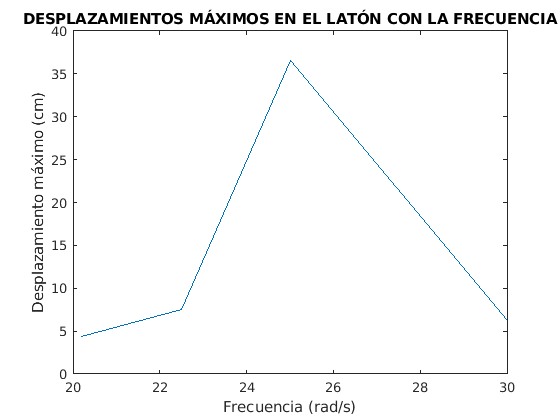


desp2 = [desplazamiento_medio_laton desplazamiento_medio_laton_22_5 desplazamiento_medio_laton_25 desplazamiento_medio_laton_30];

plot(frecuencias2,desp2)
title('DESPLAZAMIENTOS MÁXIMOS EN EL LATÓN CON LA FRECUENCIA')
xlabel('Frecuencia (rad/s)') 
ylabel('Desplazamiento máximo (cm)') 

## REPRESENTACIÓN DE LOS DESPLAZAMIENTOS DE LOS NODOS ESTUDIADOS

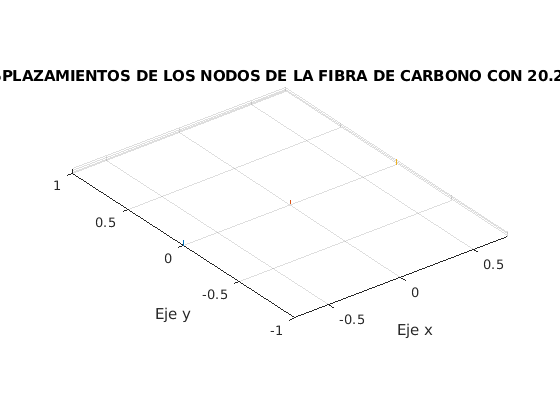

% Obtenemos una representación gráfica con los valores de X,Y y Z de los 3 nodos
% estudiados de la barra

% Realizar para cada simulatiom step para mostrar las diferencias

plot3(posiciones_nodo_0_fiber(:,1),posiciones_nodo_0_fiber(:,2),posiciones_nodo_0_fiber(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS DE LA FIBRA DE CARBONO CON 20.2 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_fiber(:,1),posiciones_nodo_28_fiber(:,2),posiciones_nodo_28_fiber(:,3))
plot3(posiciones_nodo_56_fiber(:,1),posiciones_nodo_56_fiber(:,2),posiciones_nodo_56_fiber(:,3))
hold off

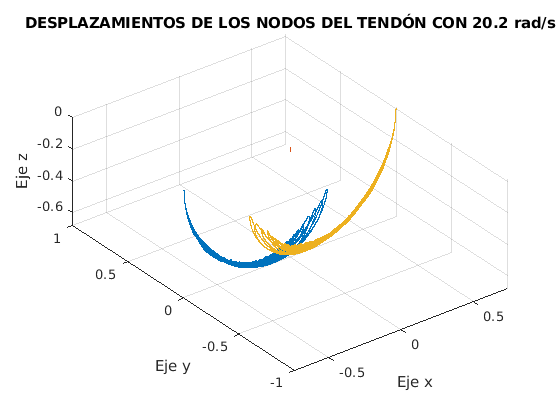


plot3(posiciones_nodo_0_tendon(:,1),posiciones_nodo_0_tendon(:,2),posiciones_nodo_0_tendon(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS DEL TENDÓN CON 20.2 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_tendon(:,1),posiciones_nodo_28_tendon(:,2),posiciones_nodo_28_tendon(:,3))
plot3(posiciones_nodo_56_tendon(:,1),posiciones_nodo_56_tendon(:,2),posiciones_nodo_56_tendon(:,3))
hold off

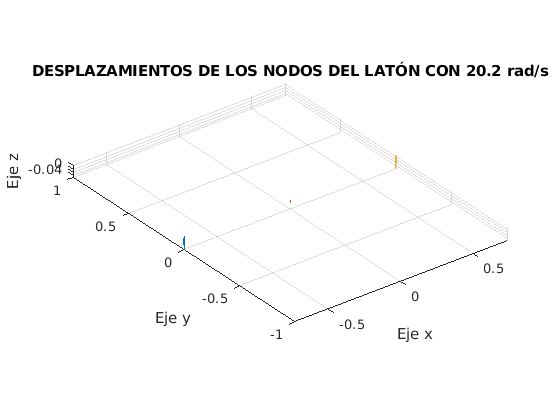


plot3(posiciones_nodo_0_laton(:,1),posiciones_nodo_0_laton(:,2),posiciones_nodo_0_laton(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS DEL LATÓN CON 20.2 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_laton(:,1),posiciones_nodo_28_laton(:,2),posiciones_nodo_28_laton(:,3))
plot3(posiciones_nodo_56_laton(:,1),posiciones_nodo_56_laton(:,2),posiciones_nodo_56_laton(:,3))
hold off

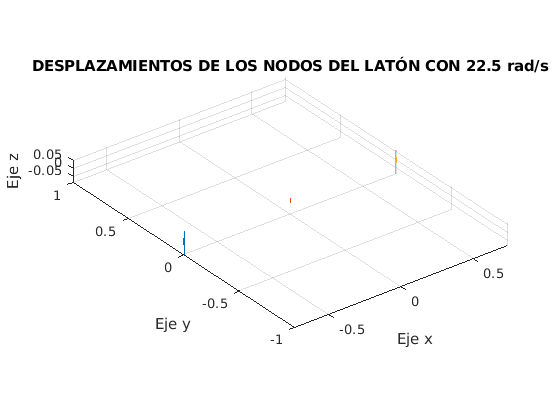


plot3(posiciones_nodo_0_laton_22_5(:,1),posiciones_nodo_0_laton_22_5(:,2),posiciones_nodo_0_laton_22_5(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS DEL LATÓN CON 22.5 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_laton_22_5(:,1),posiciones_nodo_28_laton_22_5(:,2),posiciones_nodo_28_laton_22_5(:,3))
plot3(posiciones_nodo_56_laton_22_5(:,1),posiciones_nodo_56_laton_22_5(:,2),posiciones_nodo_56_laton_22_5(:,3))
hold off

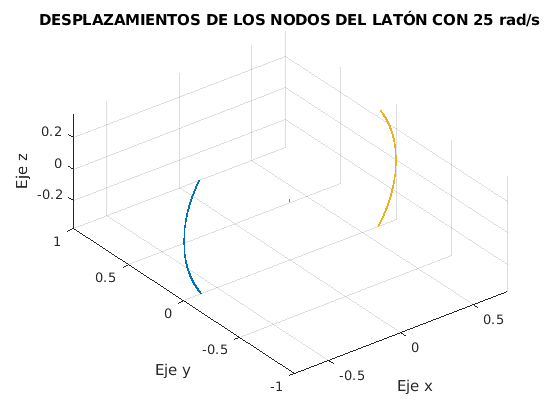


plot3(posiciones_nodo_0_laton_25(:,1),posiciones_nodo_0_laton_25(:,2),posiciones_nodo_0_laton_25(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS DEL LATÓN CON 25 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_laton_25(:,1),posiciones_nodo_28_laton_25(:,2),posiciones_nodo_28_laton_25(:,3))
plot3(posiciones_nodo_56_laton_25(:,1),posiciones_nodo_56_laton_25(:,2),posiciones_nodo_56_laton_25(:,3))
hold off

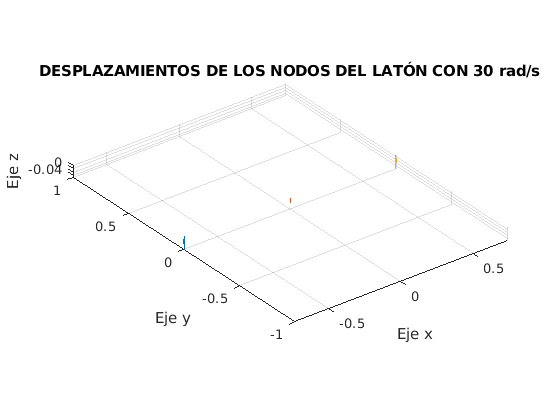


plot3(posiciones_nodo_0_laton_30(:,1),posiciones_nodo_0_laton_30(:,2),posiciones_nodo_0_laton_30(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS DEL LATÓN CON 30 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_laton_30(:,1),posiciones_nodo_28_laton_30(:,2),posiciones_nodo_28_laton_30(:,3))
plot3(posiciones_nodo_56_laton_30(:,1),posiciones_nodo_56_laton_30(:,2),posiciones_nodo_56_laton_30(:,3))
hold off

## Estudio de energía cinética según varias frecuencias

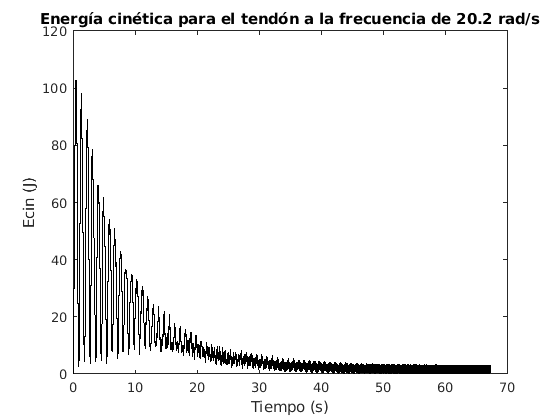

% Leemos los archivos procedentes de SOFA con los datos de energía cinética
% para las distintas frecuencias.
[vector_tiempoT,Et] = readvars('Energy_tendon_wcin.txt');
[vector_tiempoF,Ef] = readvars('Energy_fiber_wcin.txt');
[vector_tiempoL,EL] = readvars('Energy_laton_wcin.txt');
[vector_tiempoL22_5,EL22_5] = readvars('Energy_laton_wcin_22.5.txt');
[vector_tiempoL25,EL25] = readvars('Energy_laton_wcin_25.txt');
[vector_tiempoL30,EL30] = readvars('Energy_laton_wcin_30.txt');

% Realizamos las representación de las distintas energías para cada
% frecuencia estudiada
plot(vector_tiempoT,Et,'k')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Energía cinética para el tendón a la frecuencia de 20.2 rad/s')

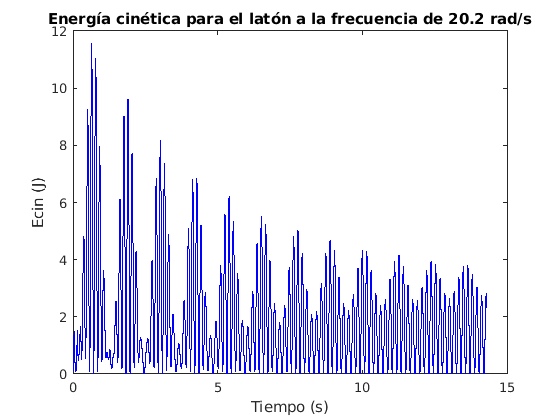

plot(vector_tiempoL,EL,'b')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Energía cinética para el latón a la frecuencia de 20.2 rad/s')

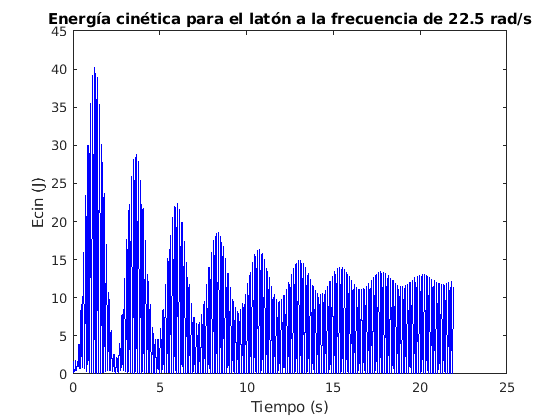

plot(vector_tiempoL22_5,EL22_5,'b')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Energía cinética para el latón a la frecuencia de 22.5 rad/s')

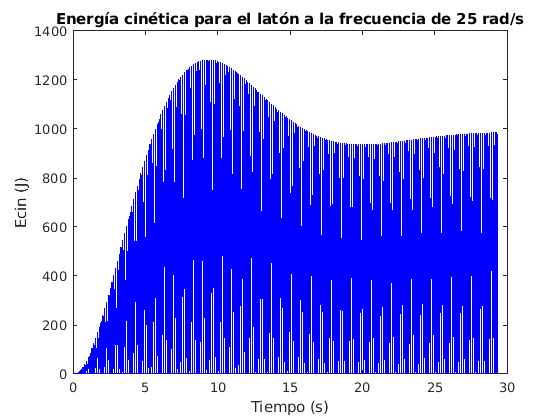

plot(vector_tiempoL25,EL25,'b')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Energía cinética para el latón a la frecuencia de 25 rad/s')

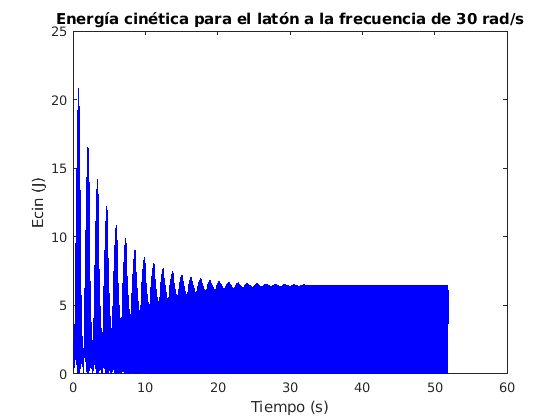

plot(vector_tiempoL30,EL30,'b')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Energía cinética para el latón a la frecuencia de 30 rad/s')

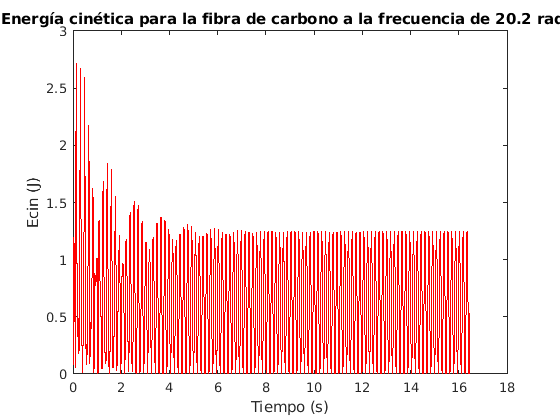

plot(vector_tiempoF,Ef,'r')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Energía cinética para la fibra de carbono a la frecuencia de 20.2 rad/s')

## Estudio de energía potencial para varias frecuencias

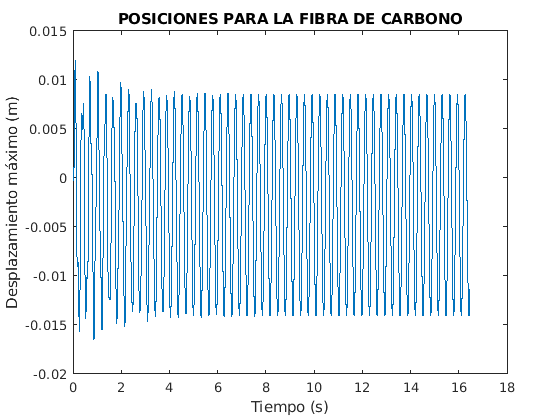

% % Leemos los archivos procedentes de SOFA con los datos de energía
% % potencial
% % para las distintas frecuencias.
plot(vector_tiempo_fiber,posiciones_nodo_0_fiber(:,3))
title('POSICIONES PARA LA FIBRA DE CARBONO')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)')

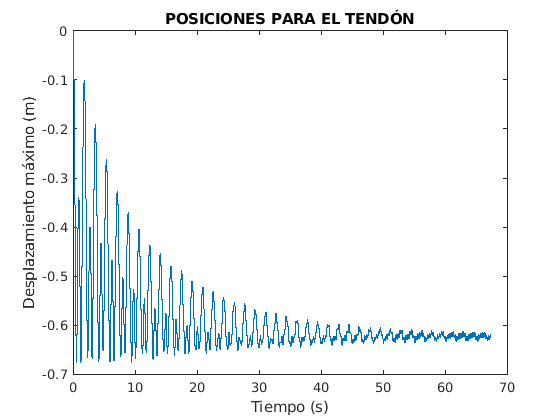


plot(vector_tiempo_tendon,posiciones_nodo_0_tendon(:,3))
title('POSICIONES PARA EL TENDÓN')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

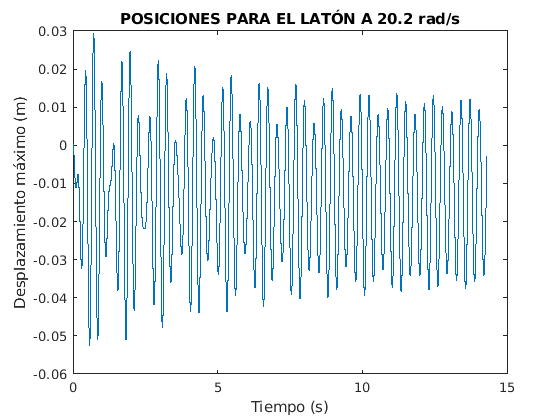


plot(vector_tiempo_laton,posiciones_nodo_0_laton(:,3))
title('POSICIONES PARA EL LATÓN A 20.2 rad/s')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

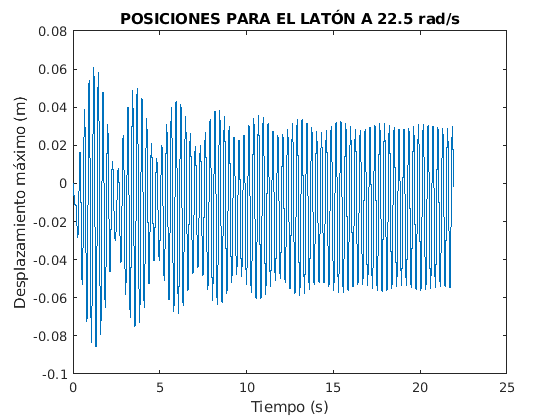


plot(vector_tiempo_laton_22_5,posiciones_nodo_0_laton_22_5(:,3))
title('POSICIONES PARA EL LATÓN A 22.5 rad/s')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

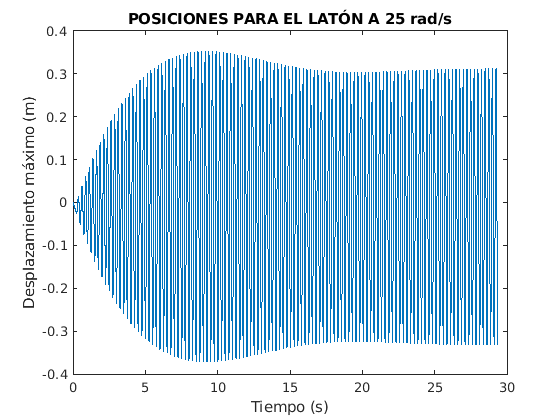


plot(vector_tiempo_laton_25,posiciones_nodo_0_laton_25(:,3))
title('POSICIONES PARA EL LATÓN A 25 rad/s')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

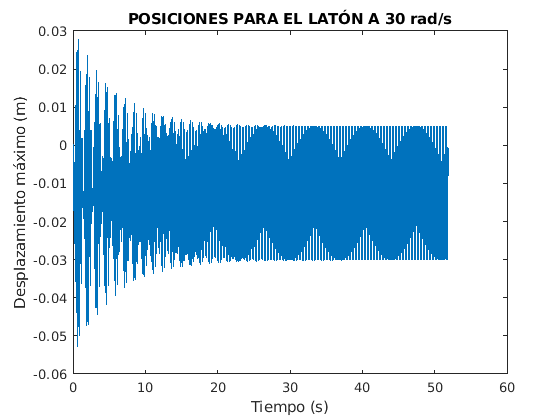


plot(vector_tiempo_laton_30,posiciones_nodo_0_laton_30(:,3))
title('POSICIONES PARA EL LATÓN A 30 rad/s')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

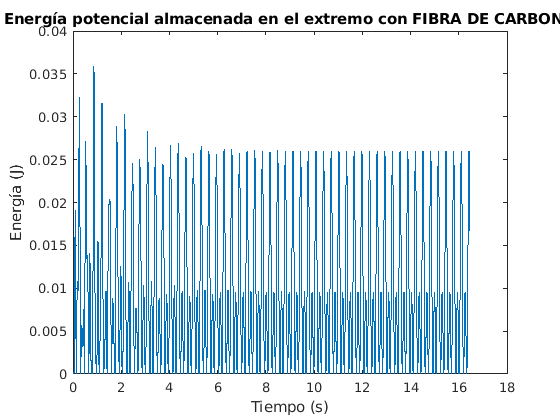


% Energías potenciales

for i=1:length(posicion_nodo_0_dcha_split_fiber)
    Epfiber(i) = 2*131.6706*0.5*(posiciones_nodo_0_fiber(i,3))^2;
end
plot(vector_tiempo_fiber,Epfiber)
title('Energía potencial almacenada en el extremo con FIBRA DE CARBONO')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

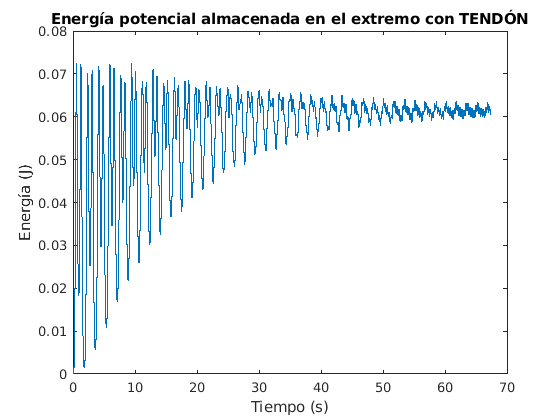


for i=1:length(posicion_nodo_0_dcha_split_tendon)
    Eptendon(i) = 2*0.1580*0.5*(posiciones_nodo_0_tendon(i,3))^2;
end
plot(vector_tiempo_tendon,Eptendon)
title('Energía potencial almacenada en el extremo con TENDÓN')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

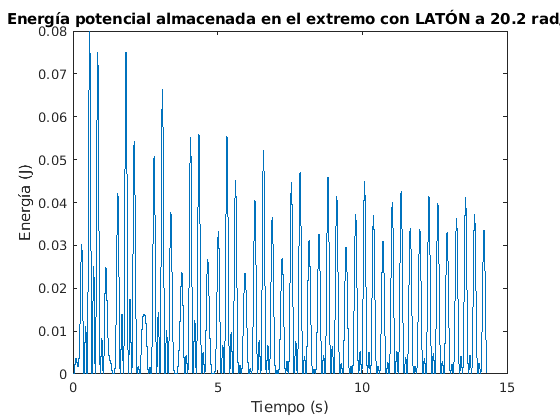


for i=1:length(posicion_nodo_0_dcha_split_laton)
    Eplaton(i) = 2*28.9675*0.5*(posiciones_nodo_0_laton(i,3))^2;
end
plot(vector_tiempo_laton,Eplaton)
title('Energía potencial almacenada en el extremo con LATÓN a 20.2 rad/s')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

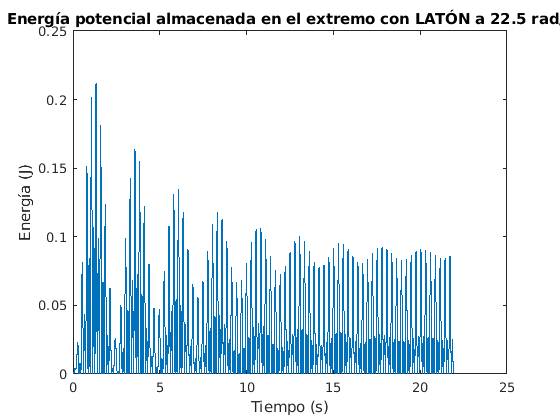


for i=1:length(posicion_nodo_0_dcha_split_laton_22_5)
    Eplaton_22_5(i) = 2*28.9675*0.5*(posiciones_nodo_0_laton_22_5(i,3))^2;
end
plot(vector_tiempo_laton_22_5,Eplaton_22_5)
title('Energía potencial almacenada en el extremo con LATÓN a 22.5 rad/s')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

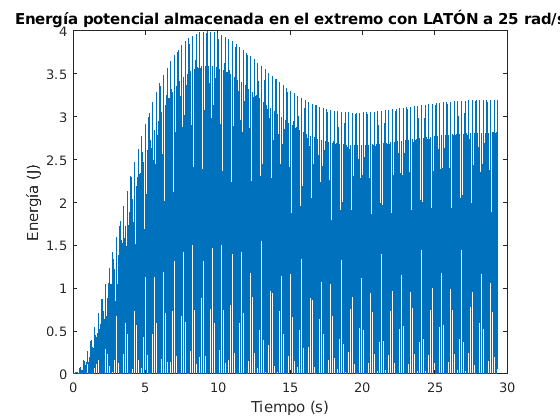



for i=1:length(posicion_nodo_0_dcha_split_laton_25)
    Eplaton_25(i) = 2*28.9675*0.5*(posiciones_nodo_0_laton_25(i,3))^2;
end
plot(vector_tiempo_laton_25,Eplaton_25)
title('Energía potencial almacenada en el extremo con LATÓN a 25 rad/s')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

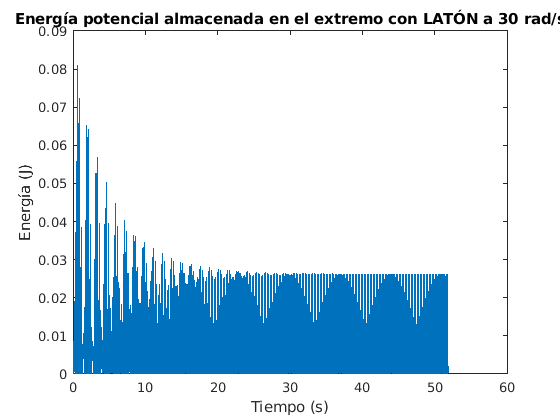


for i=1:length(posicion_nodo_0_dcha_split_laton_30)
    Eplaton_30(i) = 2*28.9675*0.5*(posiciones_nodo_0_laton_30(i,3))^2;
end
plot(vector_tiempo_laton_30,Eplaton_30)
title('Energía potencial almacenada en el extremo con LATÓN a 30 rad/s')
xlabel('Tiempo (s)')
ylabel('Energía (J)')